%%%%%%%%%%%%define continue state space%%%%%%%%%%%%%%
syms a b c p q r; 
A=[0 1 0 0;b 0 0 a;0 0 0 1;q 0 0 p];
B=[0;c;0;r];

%%%%%%%%%%%Discretization of a state-space model%%%%%%%%%
%y=theta_1
C=[1 0 0 0];
%a=-0.9421,b=82.7231,c=14.2306,p=-3.7808,q=4.9952,r=57.1120;
A=double(subs(A,{a,b,c,p,q,r},{-0.9421,82.7231,14.2306,-3.7808,4.9952,57.1120}));
B=double(subs(B,{a,b,c,p,q,r},{-0.9421,82.7231,14.2306,-3.7808,4.9952,57.1120}));
D=0;
h=0.1;
%%%%%%continue system%%%%%%%%%%%%%%%%%
sys=ss(A,B,C,D);
%%%%%%discrete system%%%%%%%%%%%%%%%%%
sys_d=c2d(sys,h);
A_d=sys_d.a

A_d =     1.4421    0.1143         0   -0.0045
    9.4370    1.4421         0   -0.0908
    0.0237    0.0008    1.0000    0.0833
    0.4814    0.0237         0    0.6845


B_d=sys_d.b

B_d =     0.0677
    1.3715
    0.2530
    4.7660


C_d=sys_d.c

C_d =      1     0     0     0


%%%%%%delay of the system%%%%%%%%%%%%%
t=0.8*h;
M=expm([A,B;0 0 0 0 0]*t);
At=M(1:4,1:4);
Bt=M(1:4,5);
M2=expm([A,B;0 0 0 0 0]*0.2*h);
A_ht=M2(1:4,1:4);
B_ht=M2(1:4,5);
A11=A_ht*At;
B11=A_ht*Bt;
B22=B_ht;
A_delay=[A11,B11;0 0 0 0 0]

A_delay =     1.4421    0.1143         0   -0.0045    0.0649
    9.4370    1.4421         0   -0.0908    1.0958
    0.0237    0.0008    1.0000    0.0833    0.2419
    0.4814    0.0237         0    0.6845    3.6657
         0         0         0         0         0


B_delay=[B22;1]

B_delay =     0.0028
    0.2757
    0.0111
    1.1002
    1.0000


C_delay=[1 0 0 0 0];
eigvalue_A_d=eig(A_d)

eigvalue_A_d =     1.0000
    2.4781
    0.4008
    0.6899


eigenvalue_A_delay=eig(A_delay)

eigenvalue_A_delay =     1.0000
    2.4781
    0.4008
    0.6899
         0


clc


%%%%%%%characters of LQ problem%%%%%%%%%%%%%%%%%%
A2=[1.0041 0.0100 0 0;0.8281 1.0041 0 -0.0093;0.0002 0.0000 1 0.0098;0.0491 0.0002 0 0.9629];
B2=[0.0007 0.1398 0.0028 0.5605]';
C2=[1 0 0 0;0 0 1 0];
Q=eye(4);
R=1;
Pf=10*eye(4);
N_input=1000;

%%%%%%%calculate with dp%%%%%%%%%%%%%%%%%%%%%%
[K_dp,P0,eigvalue_dp,N] =dp_func(A2,B2,N_input,Q,R,Pf)

This is the result of dp solution
the stable value of dp is 33

K_dp =   -46.1566   -5.2278    0.0155    0.4031


P0 = 	1.0e+04 *

    3.0780    0.3401   -0.0201   -0.0731
    0.3401    0.0382   -0.0023   -0.0082
   -0.0201   -0.0023    0.0042    0.0006
   -0.0731   -0.0082    0.0006    0.0020


eigvalue_dp =     0.5584
    0.9236
    0.9524
    0.9996


N = 33

%%%%%%%%%%solve with idare equation%%%%%%%%%%
fprintf("This is the result of idare solution\n")

This is the result of idare solution


[X,K,L]=idare(A2,B2,Q,R)

X = 	1.0e+04 *

    4.8730    0.5323   -0.1038   -0.1154
    0.5323    0.0587   -0.0114   -0.0127
   -0.1038   -0.0114    0.0125    0.0027
   -0.1154   -0.0127    0.0027    0.0030


K =    67.7456    7.5229   -0.6939   -0.9025


L =    0.9901 + 0.0000i
   0.9156 + 0.0102i
   0.9156 - 0.0102i
   0.5584 + 0.0000i


%%%%%%%%%solve with iteration%%%%%%%%%%%%%%%
aim_error=0.1;
init_error=5;
P_last=Pf;
[i,P_next] = dp_iteration(aim_error,init_error,P_last,A2,B2,Q,R)

This is the result of dp_literation solution
the  value of literation is 427

i = 427

P_next = 	1.0e+04 *

    4.8726    0.5322   -0.1037   -0.1154
    0.5322    0.0587   -0.0114   -0.0127
   -0.1037   -0.0114    0.0125    0.0027
   -0.1154   -0.0127    0.0027    0.0030


%%%%%%%%calculate with new Pf%%%%%%%%
[K_dp,P0,eigvalue_dp,N] =dp_func(A2,B2,N_input,Q,R,P_next)

This is the result of dp solution
the stable value of dp is 1

K_dp =   -67.7421   -7.5226    0.6935    0.9024


P0 = 	1.0e+04 *

    4.8726    0.5322   -0.1037   -0.1154
    0.5322    0.0587   -0.0114   -0.0127
   -0.1037   -0.0114    0.0125    0.0027
   -0.1154   -0.0127    0.0027    0.0030


eigvalue_dp =    0.5584 + 0.0000i
   0.9156 + 0.0102i
   0.9156 - 0.0102i
   0.9901 + 0.0000i


N = 1

%%%%%%%batch solution of the LQ problem%%%%%%%%%%%
[k,eigvalue,N] = batch_func(A2,B2,N_input,Q,R,Pf)

This is the result of batch solution
the stable value of batch is 33

k =   -46.1566   -5.2278    0.0155    0.4031


eigvalue =     0.5584
    0.9236
    0.9524
    0.9996


N = 33

%%%%%%%%%%%%receding horizon control%%%%%%%%%%%%
N_input=80;R=0.1;X1_steps=100;X2_steps=100;X3_steps=200;U_step=30;
X0=[pi/38 0 0 0]';
K_STEPS=100;
% [kb,omega,gama,Q_bar,R_bar] = MPC_batch(A2,B2,N_input,Q,R,Pf);
[X_K,uk,X1_k,X2_k,X3_k,UK] = xu_plot(A2,B2,N_input,Q,R,Pf,X0,X1_steps,X2_steps,X3_steps,U_step)

X_K =     0.0827    0.0767    0.0641    0.0518    0.0408    0.0313    0.0231    0.0161    0.0100    0.0049    0.0006   -0.0030   -0.0060   -0.0085   -0.0105   -0.0121   -0.0133   -0.0143   -0.0150   -0.0154   -0.0157   -0.0158   -0.0158   -0.0156   -0.0154   -0.0151   -0.0147   -0.0143   -0.0138   -0.0133   -0.0128   -0.0123   -0.0117   -0.0112   -0.0106   -0.0101   -0.0096   -0.0091   -0.0086   -0.0081   -0.0076   -0.0072   -0.0067   -0.0063   -0.0059   -0.0055   -0.0052   -0.0048   -0.0045   -0.0042
         0   -1.2001   -1.2710   -1.1457   -0.9991   -0.8627   -0.7410   -0.6334   -0.5385   -0.4551   -0.3819   -0.3178   -0.2618   -0.2129   -0.1704   -0.1336   -0.1018   -0.0744   -0.0509   -0.0308   -0.0138    0.0005    0.0125    0.0225    0.0307    0.0373    0.0426    0.0467    0.0497    0.0519    0.0534    0.0542    0.0545    0.0543    0.0538    0.0529    0.0518    0.0505    0.0490    0.0474    0.0457    0.0439    0.0420    0.0402    0.0383    0.0365    0.0347    0.0329    0.0311   

uk =    -9.0742   -1.2639    0.1814    0.4237    0.4404    0.4166    0.3873    0.3588    0.3322    0.3076    0.2850    0.2641    0.2448    0.2270    0.2106    0.1955    0.1815    0.1687    0.1568    0.1459    0.1359    0.1266    0.1181    0.1102    0.1029    0.0963    0.0901    0.0845    0.0792    0.0744    0.0700    0.0659    0.0622    0.0587    0.0555    0.0525    0.0498    0.0473    0.0450    0.0429    0.0409    0.0391    0.0375    0.0359    0.0345    0.0332    0.0320    0.0308    0.0298    0.0288


X1_k =     0.0827    0.0767    0.0641    0.0518    0.0408    0.0313    0.0231    0.0161    0.0100    0.0049    0.0006   -0.0030   -0.0060   -0.0085   -0.0105   -0.0121   -0.0133   -0.0143   -0.0150   -0.0154   -0.0157   -0.0158   -0.0158   -0.0156   -0.0154   -0.0151   -0.0147   -0.0143   -0.0138   -0.0133   -0.0128   -0.0123   -0.0117   -0.0112   -0.0106   -0.0101   -0.0096   -0.0091   -0.0086   -0.0081   -0.0076   -0.0072   -0.0067   -0.0063   -0.0059   -0.0055   -0.0052   -0.0048   -0.0045   -0.0042


X2_k =          0   -1.2001   -1.2710   -1.1457   -0.9991   -0.8627   -0.7410   -0.6334   -0.5385   -0.4551   -0.3819   -0.3178   -0.2618   -0.2129   -0.1704   -0.1336   -0.1018   -0.0744   -0.0509   -0.0308   -0.0138    0.0005    0.0125    0.0225    0.0307    0.0373    0.0426    0.0467    0.0497    0.0519    0.0534    0.0542    0.0545    0.0543    0.0538    0.0529    0.0518    0.0505    0.0490    0.0474    0.0457    0.0439    0.0420    0.0402    0.0383    0.0365    0.0347    0.0329    0.0311    0.0294


X3_k =          0   -0.0254   -0.0787   -0.1331   -0.1837   -0.2300   -0.2721   -0.3105   -0.3453   -0.3769   -0.4055   -0.4314   -0.4548   -0.4759   -0.4949   -0.5120   -0.5273   -0.5410   -0.5533   -0.5641   -0.5737   -0.5822   -0.5897   -0.5962   -0.6018   -0.6066   -0.6107   -0.6141   -0.6170   -0.6192   -0.6210   -0.6223   -0.6231   -0.6236   -0.6238   -0.6236   -0.6231   -0.6224   -0.6214   -0.6202   -0.6188   -0.6172   -0.6155   -0.6136   -0.6116   -0.6095   -0.6072   -0.6049   -0.6025   -0.6000


UK =    -9.0742   -1.2639    0.1814    0.4237    0.4404    0.4166    0.3873    0.3588    0.3322    0.3076    0.2850    0.2641    0.2448    0.2270    0.2106    0.1955    0.1815    0.1687    0.1568    0.1459    0.1359    0.1266    0.1181    0.1102    0.1029    0.0963    0.0901    0.0845    0.0792    0.0744


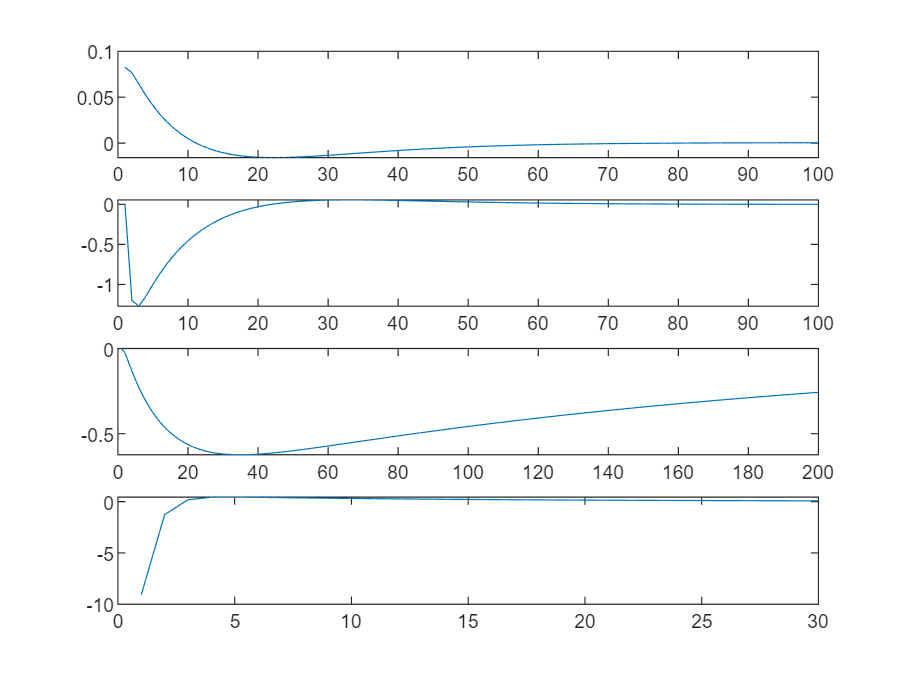


subplot(4,1,1)
plot(X1_k)
hold on 
subplot(4,1,2)
plot(X2_k)
hold on 
subplot(4,1,3)
plot(X3_k)
hold on 
subplot(4,1,4)
plot(UK)